# LABORATORIO 4. CINEMÁTICA DIRECTA- PHANTOMX PINCHER

### Integrantes:

- Marcos Alfredo Fierro Sarria

- Camilo Andres Apraez Zamora

## Solución planteada:

En este laboratorio, se llevó a cabo el estudio de la cinemática directa de un manipulador Phantom X Pincher. Inicialmente, se midieron las longitudes de los eslabones del manipulador. Con estas dimensiones y utilizando el algoritmo de Denavit-Hartenberg, se desarrolló el modelo matemático que permite determinar la posición del TCP (Tool Center Point) del manipulador en el espacio, a partir de los ángulos de las articulaciones y las longitudes de los eslabones.

### Robot Phantom X Pincher

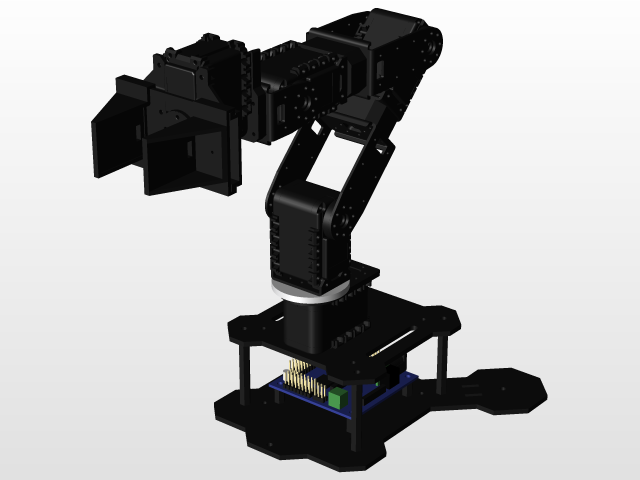

### Diagrama de sistemas de Referencia:

'''colocar aquí el diagrama de sistemas de referencia''

### Método DH:

Una vez teníamos los parámetros mencionados en base a los sistemas de referencia que tomamos anteriormente, se procede a realizar la tabla de DH, para nuestro manipulador:


$$\begin{array}{||c|c|c|c|c|}
\hline
Link \space (i) & \theta_{i} & d_{i} & \alpha_{i} & a_{i} & Offset\\ 
\hline
1 &  q_{1} & 97 & \frac{\pi}{2} & 0 & 0 \\
\hline
2 & -q_{2} & 0 & 0 & 106.7 & 1.24 \ rad \\
\hline
3 & q_{3} & 0 & 0 & 101.35& -1.24 \ rad  \\
\hline
4 & -q_{4} & 0 &   \frac{\pi}{2} & 0 &  \frac{\pi}{2} rad \\
\hline
\end{array}$$


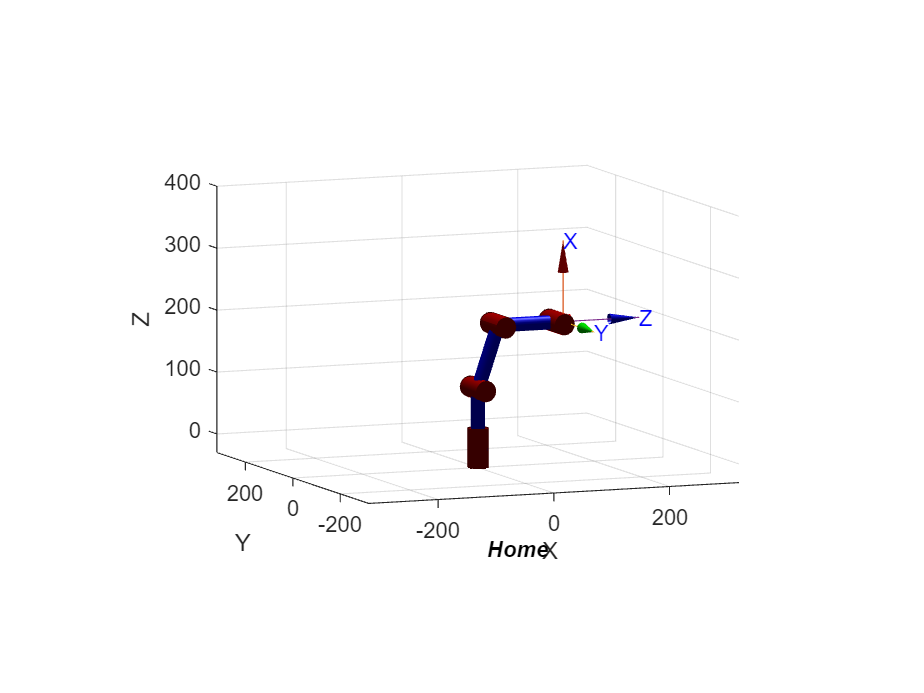

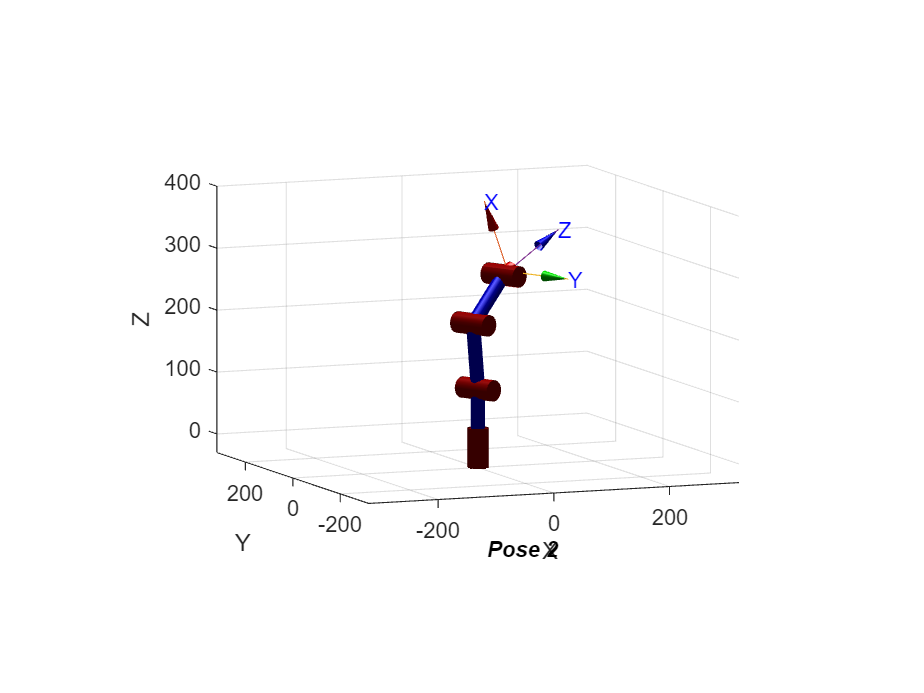

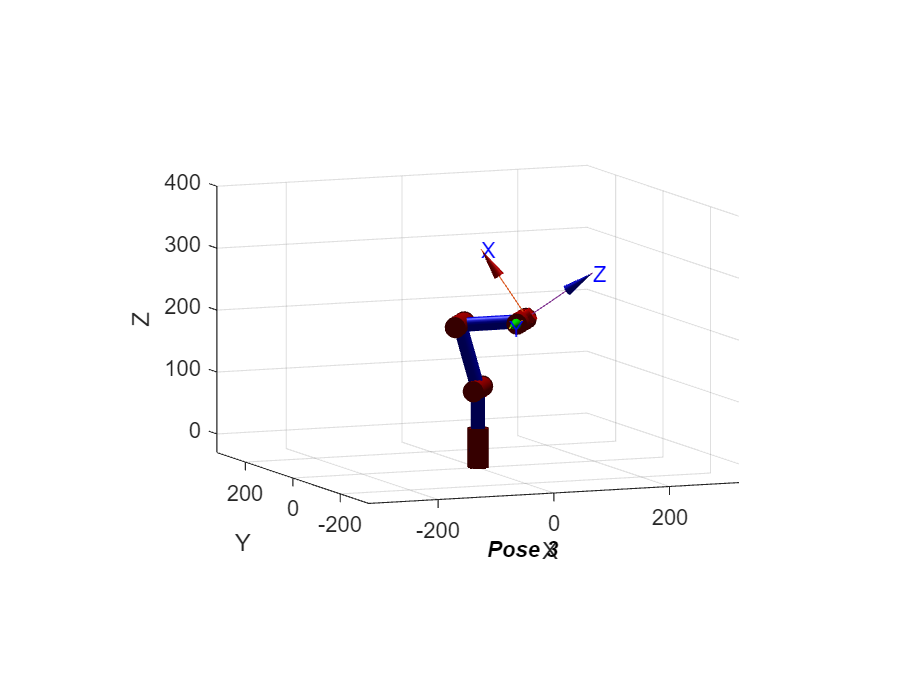

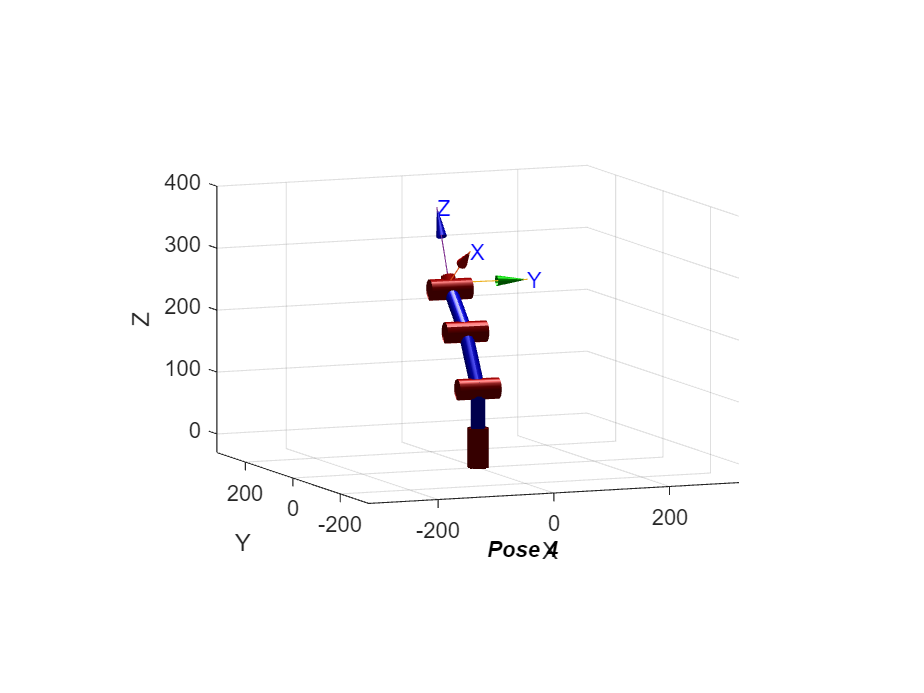

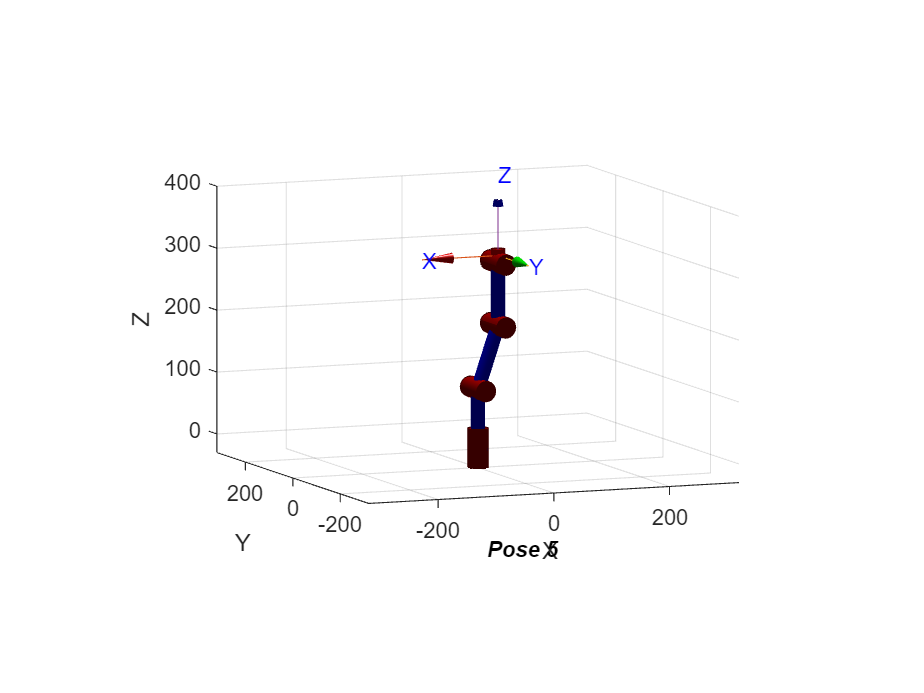

syms q1 q2 q3 q4

%Definición de parámetros
theta = [q1, -q2, q3, -q4];
d = [97, 0, 0, 0]; % Entre xi-1 y xi a lo largo de zi-1
alpha = [pi/2, 0, 0, pi/2]; % Entre zi-1 y zi a lo largo de xi
a = [0, 106.7, 101.35, 0]; % A lo largo de xi
offset = [0, 1.24, -1.24, pi/2];

% Poses en grados
q1 = [0, 0, 0, 0];
q2 = [25, 25, 20, -20];
q3 = [-35, 35, -30, 30];
q4 = [85, -20, 55, 25];
q5 = [0, 0, 90, 0];
poses = [q1; q2; q3; q4; q5];

% Nombres de las figuras (opcional)
names = {'Home', 'Pose 2', 'Pose 3', 'Pose 4', 'Pose 5'};

for i = 1:size(poses, 1)
    q = deg2rad(poses(i, :)); % Convertir grados a radianes
    
    % Orden parametros funcion link [THETA D A ALPHA SIGMA(0R,1P) OFFSET]
    DHparameters = [q(1) d(1) a(1) pi/2 0 0;
                    q(2) d(2) a(2) 0    0 1.24;
                    q(3) d(3) a(3) 0    0 -1.24;
                    q(4) d(4) a(4) pi/2 0 pi/2];
    
    L(1) = Link(DHparameters(1,:));
    L(2) = Link(DHparameters(2,:));
    L(3) = Link(DHparameters(3,:));
    L(4) = Link(DHparameters(4,:));
    
    robot_phantomX = SerialLink(L, 'name', names{i});
    robot_phantomX.tool = trotx(0) * transl(0, 0, 11.19);
    
    figure()
    robot_phantomX.plot(q);
    view([-22.3 7.9]);
    zlim([-30 400]);
end


%Cálculo de matrices homógeneas de cada de eslabón
% En esta función que definimos los ángulos están en grados
MTH_01 = calcular_DH('q1',97,0,90)

$$MTH\_01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\frac{4967757600021511\,\sin\left(q_{1}\right)}{81129638414606681695789005144064} & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \frac{4967757600021511\,\cos\left(q_{1}\right)}{81129638414606681695789005144064} & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & \frac{4967757600021511}{81129638414606681695789005144064} & 97\\ 0 & 0 & 0 & 1 \end{array}\right)$$

MTH_12 = calcular_DH('-q2+78.94',0,106.7,0)

$$MTH\_12 = \left(\begin{array}{cccc} \cos\left(q_{2}-78.94\right) & \sin\left(q_{2}-78.94\right) & 0 & 106.7\,\cos\left(q_{2}-78.94\right)\\ -\sin\left(q_{2}-78.94\right) & \cos\left(q_{2}-78.94\right) & 0 & -106.7\,\sin\left(q_{2}-78.94\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

MTH_23 = calcular_DH('q3-78.94',0,101.35,0)

$$MTH\_23 = \left(\begin{array}{cccc} \cos\left(q_{3}-78.94\right) & -\sin\left(q_{3}-78.94\right) & 0 & 101.35\,\cos\left(q_{3}-78.94\right)\\ \sin\left(q_{3}-78.94\right) & \cos\left(q_{3}-78.94\right) & 0 & 101.35\,\sin\left(q_{3}-78.94\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

MTH_34 = calcular_DH('-q4+90',0,0,90)

$$MTH\_34 = \left(\begin{array}{cccc} \cos\left(q_{4}-90\right) & \frac{4967757600021511\,\sin\left(q_{4}-90\right)}{81129638414606681695789005144064} & -\sin\left(q_{4}-90\right) & 0\\ -\sin\left(q_{4}-90\right) & \frac{4967757600021511\,\cos\left(q_{4}-90\right)}{81129638414606681695789005144064} & -\cos\left(q_{4}-90\right) & 0\\ 0 & 1 & \frac{4967757600021511}{81129638414606681695789005144064} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

MTH_4_tool = calcular_DH(0,111.9,0,0) % MTH de herramienta vista desde el link 4, hasta la mitad de la pinza

MTH_4_tool =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000  111.9000
         0         0         0    1.0000


T_cinematica_directa_ef = MTH_01* MTH_12 * MTH_23 * MTH_34 %Cinemática directa

T0_TCP = T_cinematica_directa_ef*MTH_4_tool % desde la base hasta el tcp